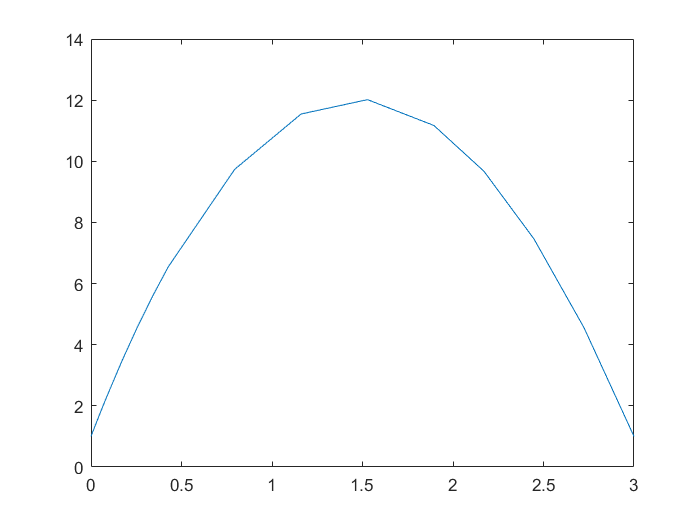

clf
[angle1, speed1] = ode_angle_and_speed(3);
[T1, M1, ~,~] = ode_penny(speed1,angle1);
plot(T1,M1(:,2))

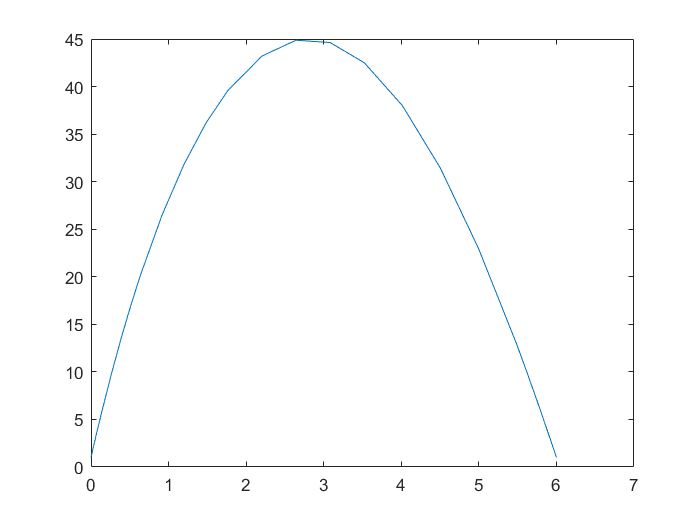


[angle2, speed2] = ode_angle_and_speed(6);
[T2, M2, ~,~] = ode_penny(speed2,angle2);
plot(T2,M2(:,2))

T1

T1 =          0
    0.0001
    0.0003
    0.0004
    0.0005
    0.0012
    0.0019
    0.0026
    0.0033
    0.0067


T2

T2 =          0
    0.0002
    0.0004
    0.0006
    0.0008
    0.0018
    0.0029
    0.0039
    0.0049
    0.0100


X1 = M1(:,1);
Y1 = M1(:,2);

X2 = M2(:,1);
Y2 = M2(:,2);
minmax = [min([X1]),max([X2]),min([Y1]),max([Y2])];

for i=1:length(T2)
    clf; hold on
    axis(minmax)
    plot(X1(i),Y1(i),'ro')
    plot(X2(i),Y2(i),'bo')
    drawnow;
    
    if i < length (T2)
        dt = T(i+1) - T(i);
        % wait for the length between the next time interval
        pause(dt);
    end
end

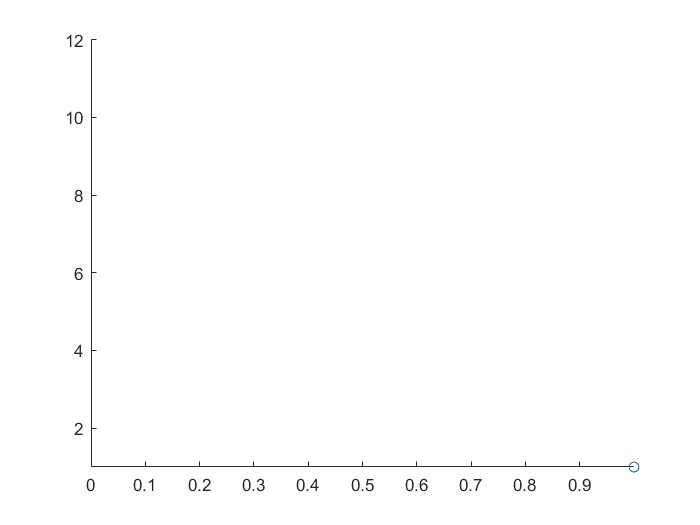

animate(T,M)

function animate(T, M)
    X = M(:,1);
    Y = M(:,2);
    minmax = [min([X]),max([X]),min([Y]),max([Y])];
    
    for i=1:length(T)
        clf; hold on
        axis(minmax)
        plot(X(i),Y(i),'o')
        drawnow;
        
        if i < length (T)
            dt = T(i+1) - T(i);
            pause(dt);
        end
    end
end